## Variabile speciale

Sunt variabile rezervate de către Matlab, cu valori prealocate, ce prezintă în general proprietăți speciale, fiind utile într-un număr mare de aplicații. 

Este recomandată în general evitarea asignării de către utilizator a unor valori oarecare pentru aceste variabile; în unele cazuri acest fapt este interzis de către Matlab (‘end’), iar în alte situații există soluții alternative (‘i’/’j’).

Cazurile nefavorabile sunt cele în care se poate suprascrie variabila specială, situație în care nu se poate utiliza valoarea sa preasignată de către Matlab, până la ștergerea noii valori din Workspace.

% Ștergerea variabilelor din Workspace anterior generate
clear;

b = 5/Inf;
Inf = 2;
a = 5/Inf;

### Variabila** ans**

Reține rezultatul unei operații/funcții în cazul în care nu a fost specificată o varibilă de ieșire.

% Ștergerea variabilelor din Workspace anterior generate
clear;

[1, -2, 4; 6, 7, -4]

ans =      1    -2     4
     6     7    -4


### Variabilele complexe **i, j**

Ambele variabile au același rol, respectv reprezentarea numerelor complexe. În cazul asignării altor valori lui i/j (de ex. in for), se pot utiliza oricând valorile lor complexe, specificând ‘1i’/’1j’.

% Ștergerea variabilelor din Workspace anterior generate
clear;

a = ones(1,5);
for i = 1:5
    a(i) = a(i) - 1i*a(i);
end
disp(a);

   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i   1.0000 - 1.0000i



### Variabila **Inf**

Îndeplinește rolul $\prime \infty^{\prime }$.

% Ștergerea variabilelor din Workspace anterior generate
clear;

a = 7/Inf;
b = -99999999 + Inf;

### Variabila **NaN** (Not a Number)

Apare în cazul situațiilor de nedeterminare.

% Ștergerea variabilelor din Workspace anterior generate
clear;

a = Inf/Inf;
c = Inf - Inf;
A_mat = [4 0; -5 3];
B_mat = [3 0; -3 4];
A_mat./B_mat

ans =     1.3333       NaN
    1.6667    0.7500


### Variabila **end**

 Îndeplinește rolul ultimului indice pe o anumită dimensiune.

% Ștergerea variabilelor din Workspace anterior generate
clear;

A_mat = [-2, 4, 7; 12, 40, -45];
B_mat = A_mat(end-1:end,end-1:end);

disp(B_mat)

     4     7
    40   -45



### Variabila **e**

Este folosită în cadrul notației știinifice. Aceasta are ca efect multiplicarea cu puterile lui 10 și este util în reprezentarea variabilelor în virgulă mobilă sau a unor mărimi fizice utilizând multiplii sau submultiplii unităților de măsură în S.I. (Sistemul Internațional)

% Ștergerea variabilelor din Workspace anterior generate
clear;

a = 2.4e2

a = 240

b = 10e-3

b = 0.0100

### Variabilele **realmax și realmin**

Reprezintă cea mai mare, respectiv cea mai mică variabilă de tip real ce poate fi utilizată în Matlab.

% Ștergerea variabilelor din Workspace anterior generate
clear;

disp(['Cea mai mare variabilă: ', num2str(realmax), newline, 'Cea mai mică variabilă: ', num2str(realmin)  ])

Cea mai mare variabilă: 1.797693134862316e+308
Cea mai mică variabilă: 2.2251e-308



Inf/realmax

ans = Inf

### Variabila **pi**

Utilă în realizarea oricărei aplicații ce presupune simularea unor fenomene oscilatorii.

pi

ans = 3.1416

sin(pi/2)

ans = 1

## Script-uri și funcții

### Script-uri

- Varianta standard de aplicație Matlab;

- Grup de instrucțiuni a căror execuție pornește la activarea unei comenzi “Run”;

- În cadrul scriptului se specifică atât operațiile specifice aplicației, cât și variabilele de intrare;

- În urma execuției scriptului, se returnează în Workspace atât variabilele de ieșire, cât și toate variabilele intermediare și de intrare specificate în script;

- Eventualele erori prezente într-o aplicație de tip script sunt mult mai ușor de identificat decât în cazul unei funcții, deoarece script-ul pune la dispoziția utilizatorului toate variabilele aplicației;

- Scriptul poate fi considerat forma cea mai generală a unei funcții, la care nu se specifică nici un argument de intrare (sunt generate în aplicație sau preluate automat din Workspace) și la care nu se specifică nici arg. de ieșire (deoarece toate variabilele utilizate în aplicație sunt considerate argumente de ieșire);

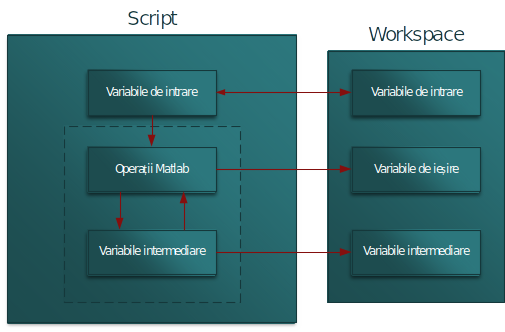

Este indicat:

- ca scripturile să înceapă cu o descriere a scopului acestora (folosind comentariile %) și cu specificarea numeilui și datelor de contact ale autorului 

- ca toți parametrii să fie definiți sub formă de variabile la începutul script-ului și să se adauge comentarii despre funcționalitatea acestora

- să se folosească celule pentru o mai bună organizare a codului. (Celulele sunt "paragrafe" ce conțin cod și se evidențiează prin folosirea %%)

- ca un script să aibă un singur scop clar și bine definit

- în cazul în care sunt obiective de atins, ca acestea să fie enumerate în introducere (partea de început)

- să se separe printr-un spațiu elementele constituente ale script-ului pentru a crește lizibilitatea

Un script se poate rula linie cu linie, selectând linia respectivă și folosind click dreapta sau F9. O celulă se poate rula în întregime folosind combinația CTRL+Enter. Pentru a putea rula un script în întregime se utilizează F5 sau butonul Run din interfața grafică.

### Funcții

- Se poate obține dintr-un script prin eliminarea intrărilor și introducerea unui antet cu structura generală:

- function [o1,o2,o3,…]=nume_functie(i1,i2,i3,...)

- Va genera în Workspace doar variabilele de ieșire

- Numele funcției trebuie să corepundă numelui fișierului ‘.m’ ce va conține funcția, fișier salvat în Current Folder pentru a pute fi apelat

- Apelarea se poate face fie în linie de comandă, fie într-un alt script sau altă funcție, evident sub forma: [o1,o2,o3,…]=nume_functie(i1,i2,i3,...)

- Variabilele de intrare pot fi generate anterior și preluate din Workspace sau introduse direct ca argumente la apelarea funcției

- Se utilizează în general pentru diferite testări/simulări ca forma finală a unei aplicații a cărei funcționare a fost verificată sub formă de script

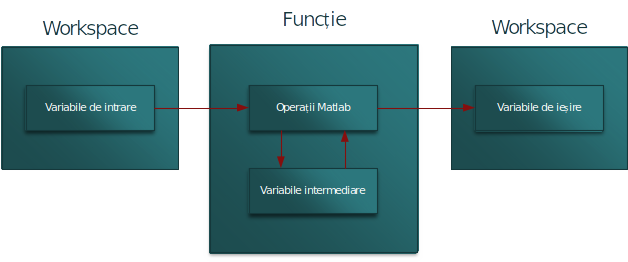

- Este posibil să se parcurgă codul din cadrul unei funcții la rulare setând un breakpoint și apoi folosind butonul "Step in". În această situație propmt-ul din Command Window se va modifica astfel: K>>

- Este indicat să se creeze un "help text" al funcțiilor. Acesta va fi vizualizat la apelarea comenzii help *nume_funcție. *Este recomandat să conțină următoarele detalii:

-     Numele funcției, o listă ordonată a variabilelor de intrare și variabilelor de ieșire

-     Descrierea funcției

-     O listă detaliată a parametrilor de iintrare obligatorii și opționali

-     O listă detaliată a parametrilor de ieșire

-     Exemple de utilizare

-     Informații despre autor/date de contact

- **NU SUPRASCRIEȚI FUNCȚIILE PREDEFINITE DIN MATLAB! (folosiți funcția which *****nume_funcție *****pentru a afla dacă funcția este deja definită)**

## **Interacțiunea cu datele**

Datele specifice Matlab sunt fișiere cu extensia **mat. **

### **Importarea datelor specifice Matlab**

% Ștergerea variabilelor din Workspace anterior generate
clear;

load testmat.mat;
date_matlab = load("testmat.mat")

date_matlab = struct with fields:
    varA: [3×9 double]
    varB: [1×45 double]
    varC: [10×10 double]


### Importarea datelor externe Matlab

- Este posibilă importarea de date numerice din fișiere text dacă acestea au un număr identic de coloane pentru fiecare rând în parte.

% Ștergerea variabilelor din Workspace anterior generate
clear;

data_txt = dlmread('test_datafile.txt');

- Importarea datelor din Microsoft Excel

data_xls =xlsread("test_excelfile.xlsx")

data_xls =      1    34
     2     4
     3    46
     4     7
     5     6
     6   345
    45   345
     2     2
     2     2
     4     3


### Exportarea datelor din Matlab în fișiere Matlab

% Ștergerea variabilelor din Workspace anterior generate
clear;

% Salvarea tuturor datelor din Workspace în variabila matlab.mat
save;


Saving to: C:\Users\jacks\Desktop\Facultate\Anul 1\Cursuri\Sem2\Info_Aplic\MATLAB\Laborator\Lab. 2\matlab.mat




% Salvarea unor variabile specifice
a = 5;
save("test_save.mat", "a")
save test_save_2.mat a

### Exportarea datelor în fișiere externe Matlab

% Salvarea într-un fișier text
b = [12 4 5; -5 -6 7];
dlmwrite('save_data.txt',b,','); % virgula este folosită pentru delimitare

% Salvarea într-un fișier Excel

T = table(['M';'F';'M'],[45 45;41 32;40 34], ...
    {'NY';'CA';'MA'},[true;false;false],[1;2;3])

T = 3×5 table
    Var1      Var2       Var3     Var4     Var5
    ____    ________    ______    _____    ____

     M      45    45    {'NY'}    true      1  
     F      41    32    {'CA'}    false     2  
     M      40    34    {'MA'}    false     3  


writetable(T,'save_to_excel.xls')

### Afișarea variabilelor folosind funcția disp

% Ștergerea variabilelor din Workspace anterior generate
clear;

a = 3.5;
b = -5;

disp(a);

    3.5000



disp([a, b])

    3.5000   -5.0000



## Exerciții

- Scrieți o funcție care să returneze valoarea minimă a unui vector. Se va folosi funcția sort în locul funcției min pentru a obține valoarea minimă.

clear;
X = randi(12,1,10);
mn = minimum_value_of_vector(X);

- Aveți de scris o nouă funcție. Vi se pun la dispoziție următoarele nume pentru funcție: mmean, mean2, nanmean, fftmean, meen. Precizați care dintre numele enumerate sunt recomandate pentru a denumi funcția ( utilizați funcția which).

 which mmean;

'mmean' not found.


which mean2;

'mean2' not found.


which nanmean;

C:\Program Files\MATLAB\R2020b\toolbox\stats\stats\nanmean.m


which fftmean;

'fftmean' not found.


which meen;

'meen' not found.


disp(["Sunt disponibile: " + "mmean, " + "mean2, " + "fftmean, " + "meen."]);

Sunt disponibile: mmean, mean2, fftmean, meen.


- Creați o funcție care va returna o matrice *m*$x$*n *ce conține numere aleatoare (funcția randn), apoi înmulțiti matricea cu un număr aleator (funcția rand). Variabilele de intrare sunt reprezentate de dimensiunile matricei, iar la ieșire se va returna matricea și numărul aleator cu care s-a înmulțit.

nr_lin = input("Introduceți numărul de linii: ");
nr_col = input("Introduceți numărul de coloane: ");
[random_matrix, random_number] = random_operations(nr_lin,nr_col);

- Creați un script care va genera o matrice (dimensiunea la alegre) ce conține numere întregi între 0 și 10. Calculați numărul elementelor matricei (funcțiile size, prod, numel).

%%Scriptul este Generare_matrice.m

- Creați o funcție care să transforme vectorul 1:6 în vectorul [1, 2, 3, 1, 2, 3]. Se va folosi funcția mod.

V = 1:6;
V = aplica_mod_3(V);

- Creați o matrice *mat* *2x3 *ce conține numere aleatoare. Verificați care este diferența dintre următoarele linii de cod: a) dlmwrite(’test1.txt’, mat ,’ ’) b) dlmwrite(’test2.txt’,’mat’,’ ’).

M = rand(2,3);
dlmwrite('test1.txt',M,' ');%%afișează elementele matricei
dlmwrite('test2.txt','M',' ');%%afișează numele matricei

- Funcția *csvread* este folosită pentru a importa fișiere de tip CSV (comma separated values). Generați un fișier csv folosind un utilitar (Excel, text) și importați-l în Matlab. Folosind *csvwrite *exportați valorile într-alt fișier csv. Verificați dacă valorile sunt identice. Vă veți folosi de funcția help.

opts = delimitedTextImportOptions("NumVariables",22);
opts.DataLines = [2,Inf];
opts.Delimiter = ",";
opts.VariableNames = ["time", "latitude", "longitude", "depth", "mag", "magType", "nst", "gap", "dmin", "rms", "net", "id", "updated", "place", "type", "horizontalError", "depthError", "magError", "magNst", "status", "locationSource", "magSource"];
opts.VariableTypes = ["string","double", "double", "double", "double", "categorical", "string", "double", "double", "double", "string", "string", "string", "string", "categorical", "double", "double", "double", "double", "categorical", "string", "string"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts = setvaropts(opts, ["time", "nst","net", "id", "updated", "place", "locationSource", "magSource"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["time", "magType", "nst", "net", "id", "updated", "place", "type", "status", "locationSource", "magSource"], "EmptyFieldRule", "auto");

Table = readtable("significant_week.csv", opts);
clear opts;
writetable(Table,"significant_week_test.csv");
%%astfel am citit si am salvat. opts face ca text libere sa ramana asa, unde era NaN, a ramas asa.